# Chapter 04: Support Vector Machines

close all; clear all;
warning('off','all');

## The case of two linearly separable classes

The blue dots are labeled negatively and the red crosses are labeled positively. 

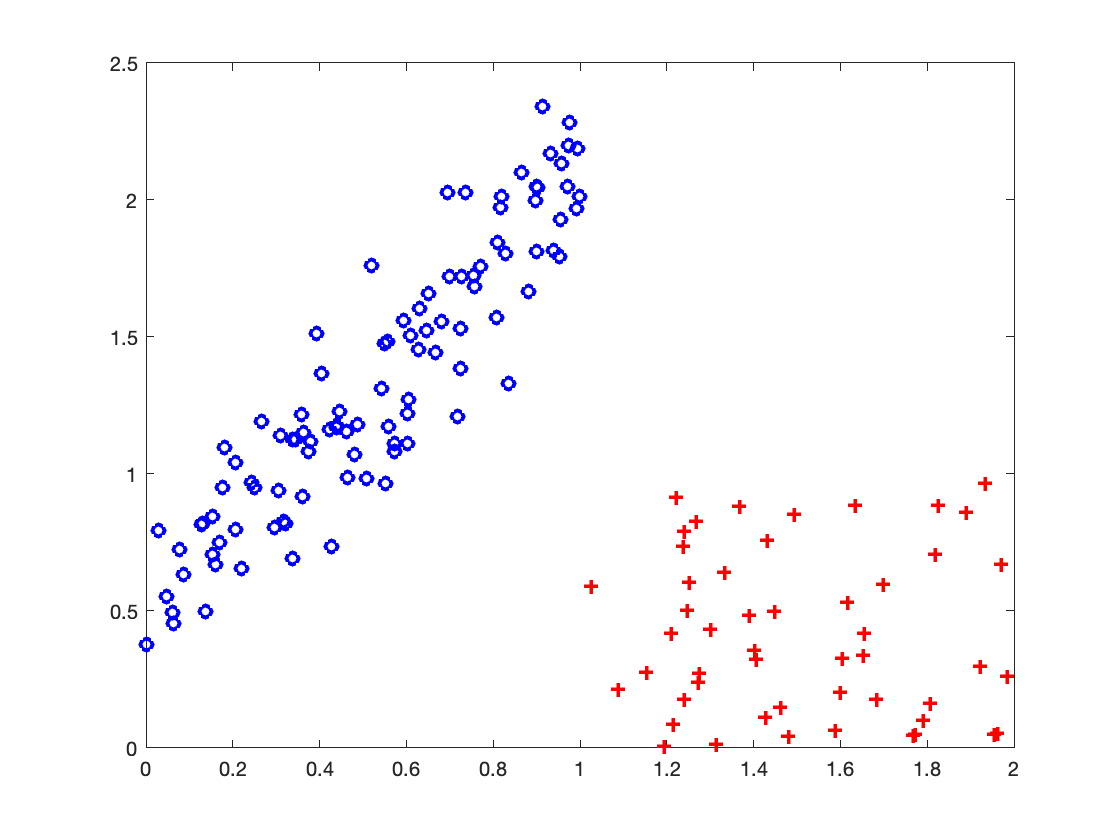

% generate the data
m0 = 100;
m1 = 50;
X0 = zeros(m0,2); 
X0(:,1) = rand(m0,1);                          % abscissae of the blue dots
X0(:,2) = 3/2*X0(:,1) + 1/2 + 0.2*randn(m0,1); % their ordinates
X1 = zeros(m1,2);
X1(:,1) = 1 + rand(m1,1);                      % abscissae of the red crosses
X1(:,2) = rand(m1,1);                          % their ordinates
figure(1)
plot(X0(:,1),X0(:,2),'bo',X1(:,1),X1(:,2),'r+','LineWidth',2)
hold on

#### The separating "hyperplane" produced by a linear feasibility program

cvx_quiet true
cvx_begin
variable w_feas(2)
variable b_feas
minimize 1
subject to
X0*w_feas-b_feas <= -1;
X1*w_feas-b_feas >= +1;
cvx_end

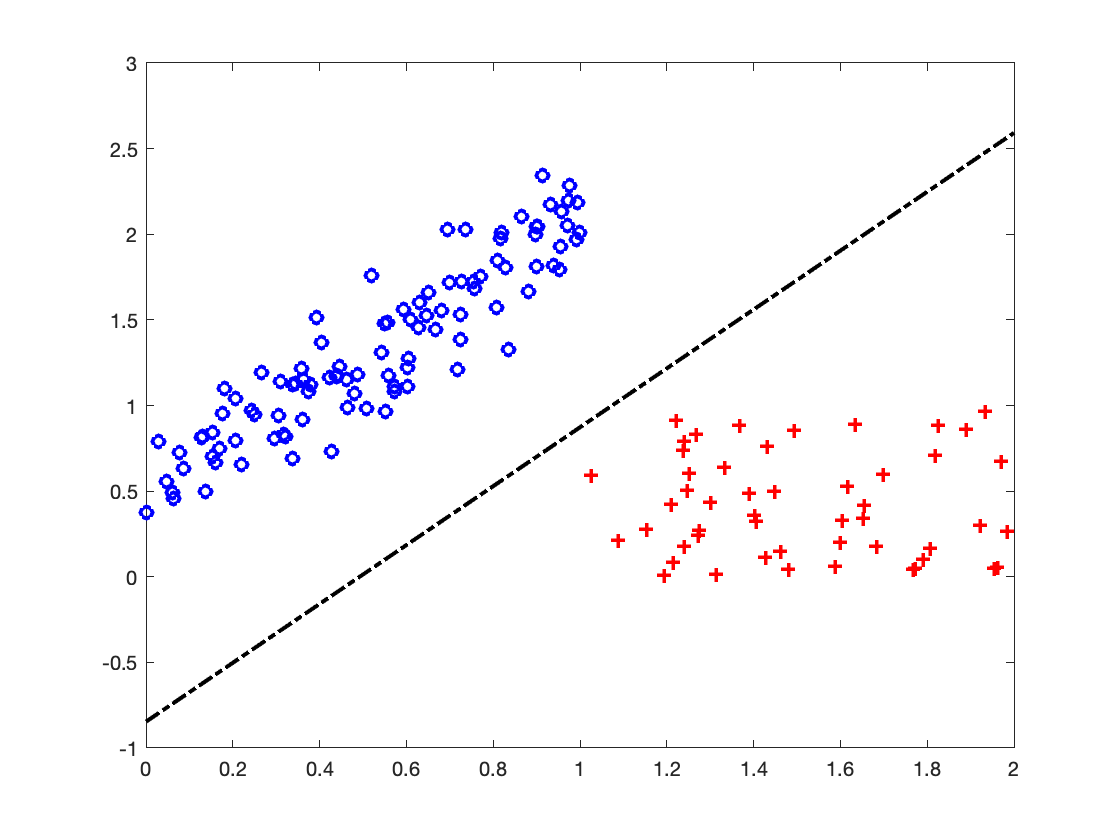

% visualize the "hyperplane" produced by a linear feasibility program (in black)
grid_x = linspace(0,2,20);
plot(grid_x,(-w_feas(1)*grid_x+b_feas)/w_feas(2),'k-.','LineWidth',2);

#### The separating "hyperplane" produced by the perceptron algorithm

X_tilde = [X0 ones(m0,1); X1 ones(m1,1)];
y = [-ones(m0,1); +ones(m1,1)];
w_perc = zeros(3,1);
obj_perc = y.*(X_tilde*w_perc);     % to be entrywise positive at the end on the loop 
while min(obj_perc) <= 0
    [~,i] = min(obj_perc);
    w_perc = w_perc + (y(i)/norm(X_tilde(i,:))^2)*X_tilde(i,:)';
    obj_perc = y.*(X_tilde*w_perc);
end

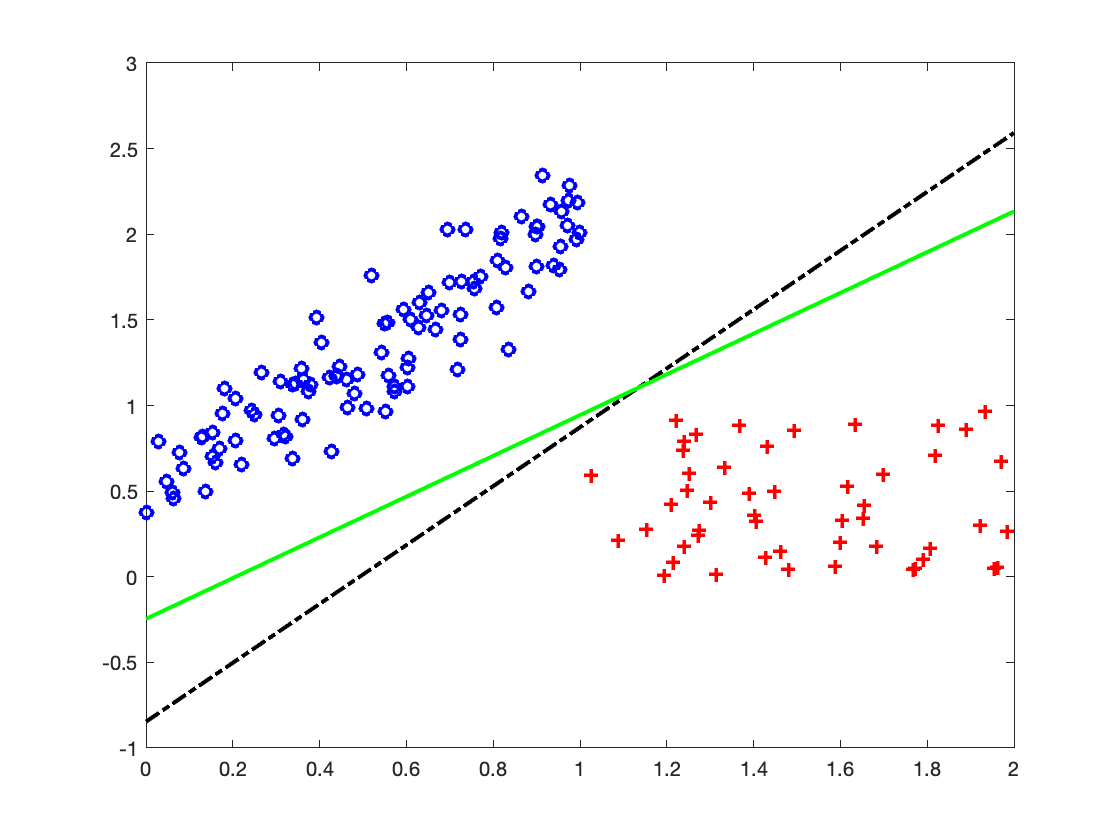

% visualize the "hyperplane" produced by the percepton alogirthm (in green)
plot(grid_x,(-w_perc(1)*grid_x-w_perc(3))/w_perc(2),'g','LineWidth',2);

#### The separating "hyperplane" produced by hard SVM

cvx_begin
variable w_hsvm(2)
variable b_hsvm
minimize norm(w_hsvm)
subject to 
X0*w_hsvm-b_hsvm <= -1;
X1*w_hsvm-b_hsvm >= +1;
cvx_end

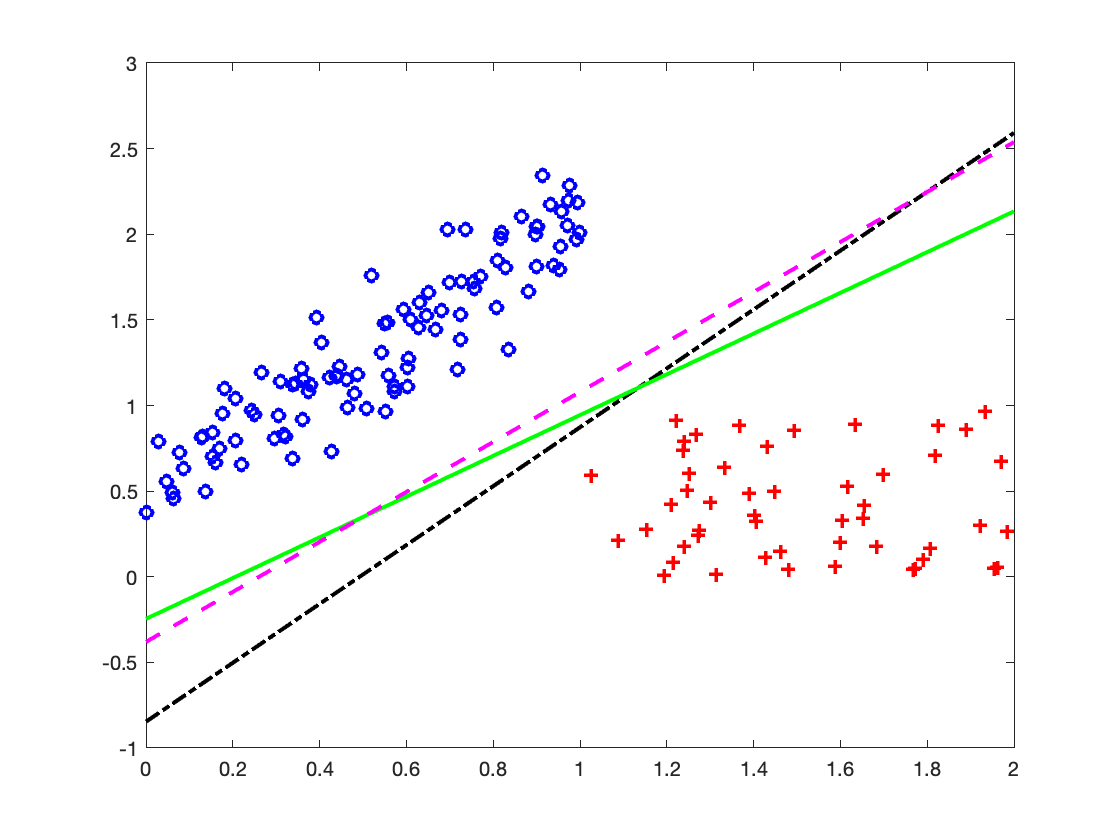

% visualize the "hyperplane" produced by hard SVM (in magenta)
plot(grid_x,(-w_hsvm(1)*grid_x+b_hsvm)/w_hsvm(2),'m--','LineWidth',2);

## The case of two almost linearly separable classes

The blue dots are still labeled negatively and the red crosses are still labeled positively.

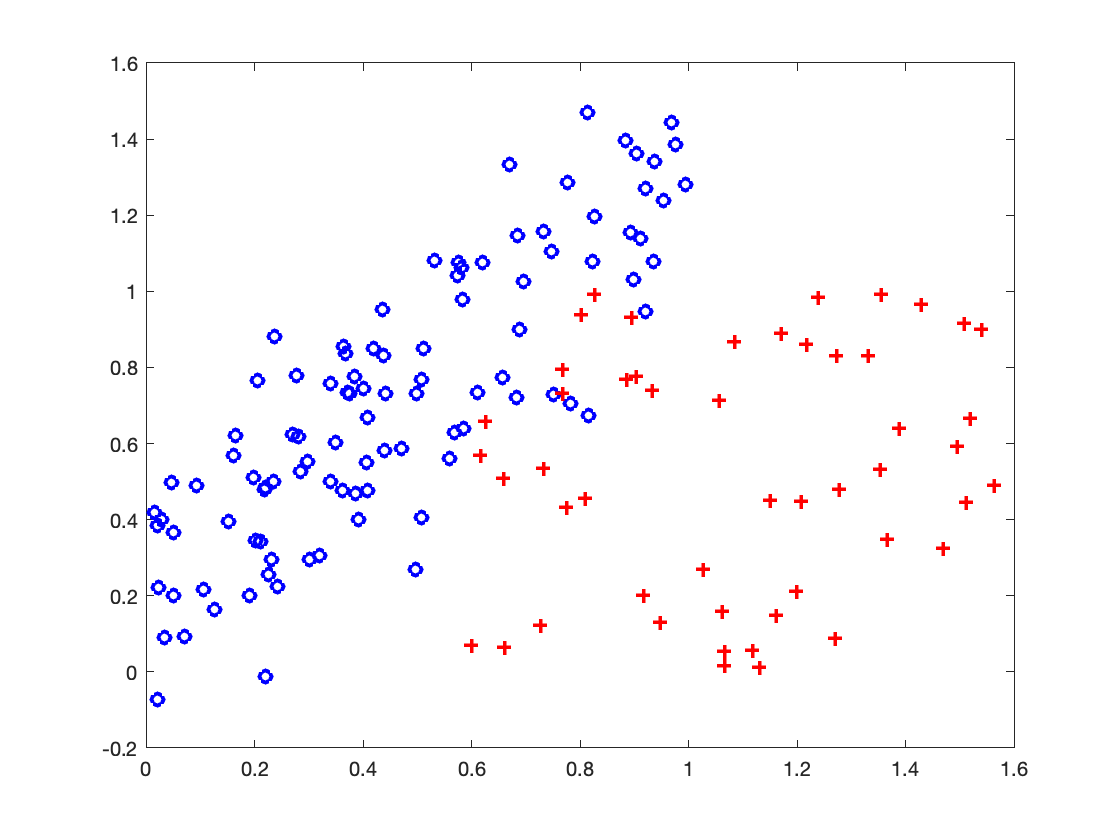

% generate the data
clear all;
m0 = 100;
m1 = 50;
X0 = zeros(m0,2); 
X0(:,1) = rand(m0,1);                          % abscissae of the blue dots
X0(:,2) = X0(:,1) + 1/4 + 0.2*randn(m0,1);     % their ordinates
X1 = zeros(m1,2);
X1(:,1) = 0.6 + rand(m1,1);                    % abscissae of the red crosses
X1(:,2) = rand(m1,1);                          % their ordinates
figure(2)
plot(X0(:,1),X0(:,2),'bo',X1(:,1),X1(:,2),'r+','LineWidth',2)
hold on

#### The "hyperplane" produced by soft SVM

cvx_quiet true
lambda = 1e-3;
cvx_begin
variable w_ssvm(2)
variable b_ssvm
variable xi_ssvm(m0+m1) nonnegative
minimize norm(w_ssvm) + (1/lambda)*sum(xi_ssvm)
subject to 
X0*w_ssvm-b_ssvm <= -1 + xi_ssvm(1:m0);
X1*w_ssvm-b_ssvm >= +1 - xi_ssvm(m0+1:end);
cvx_end

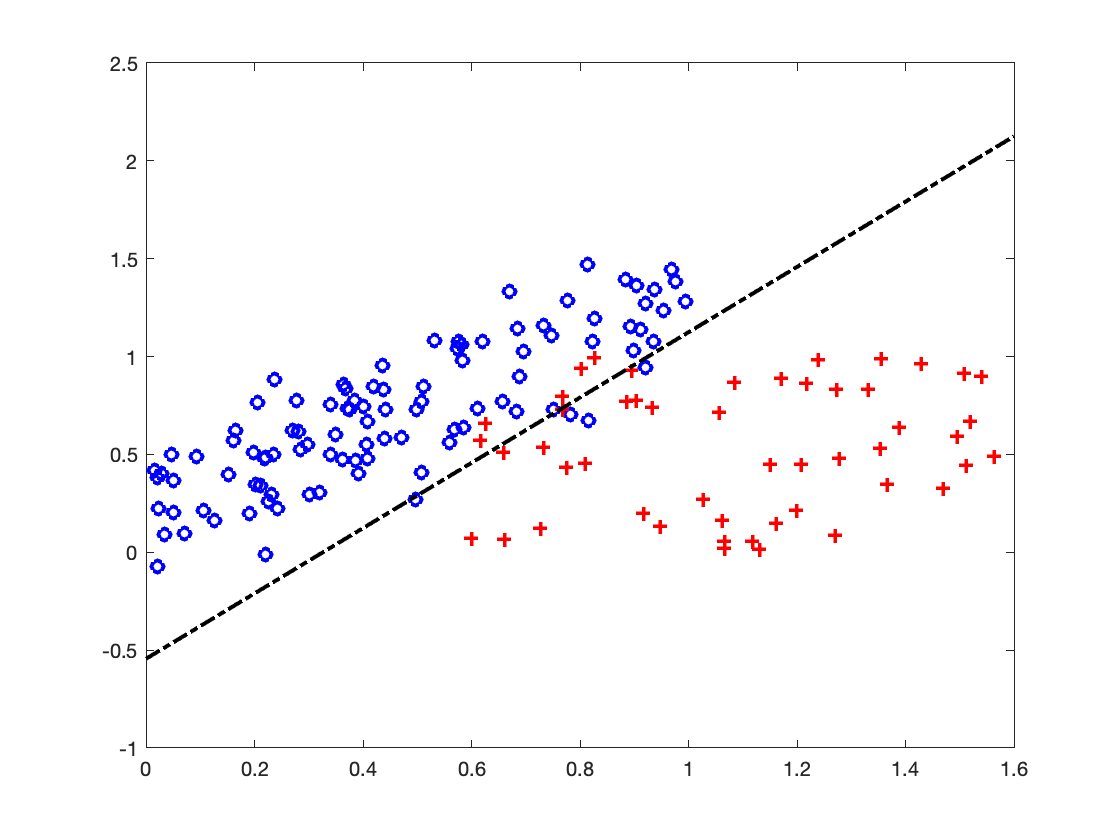

% visualize the "hyperplane" produced by soft SVM
grid_x = linspace(0,1.6,20);
plot(grid_x,(-w_ssvm(1)*grid_x+b_ssvm)/w_ssvm(2),'k-.','LineWidth',2);

## The case of two classes clearly not linearly separable

The function performing kernel SVM for a generic kernel is defined at the end of the document.

#### In the first example, one utilizes a polynomial kernel. 

As usual, the blue dots are labeled negatively and the red crosses positively.

% generate the data
clear all; clc;
m0 = 100;
m1 = 50;
X0 = zeros(m0,2); 
X0(:,1) = 6*rand(m0,1);                          % abscissae of the blue dots
X0(:,2) = sin(X0(:,1)) + 0.5*rand(m0,1);         % their ordinates
X1 = zeros(m1,2);
X1(:,1) = 6*rand(m1,1);                          % abscissae of the red crosses
X1(:,2) = sin(X1(:,1)) - 0.5*rand(m1,1);         % their ordinates
figure(3)
plot(X0(:,1),X0(:,2),'bo',X1(:,1),X1(:,2),'r+')
hold on 

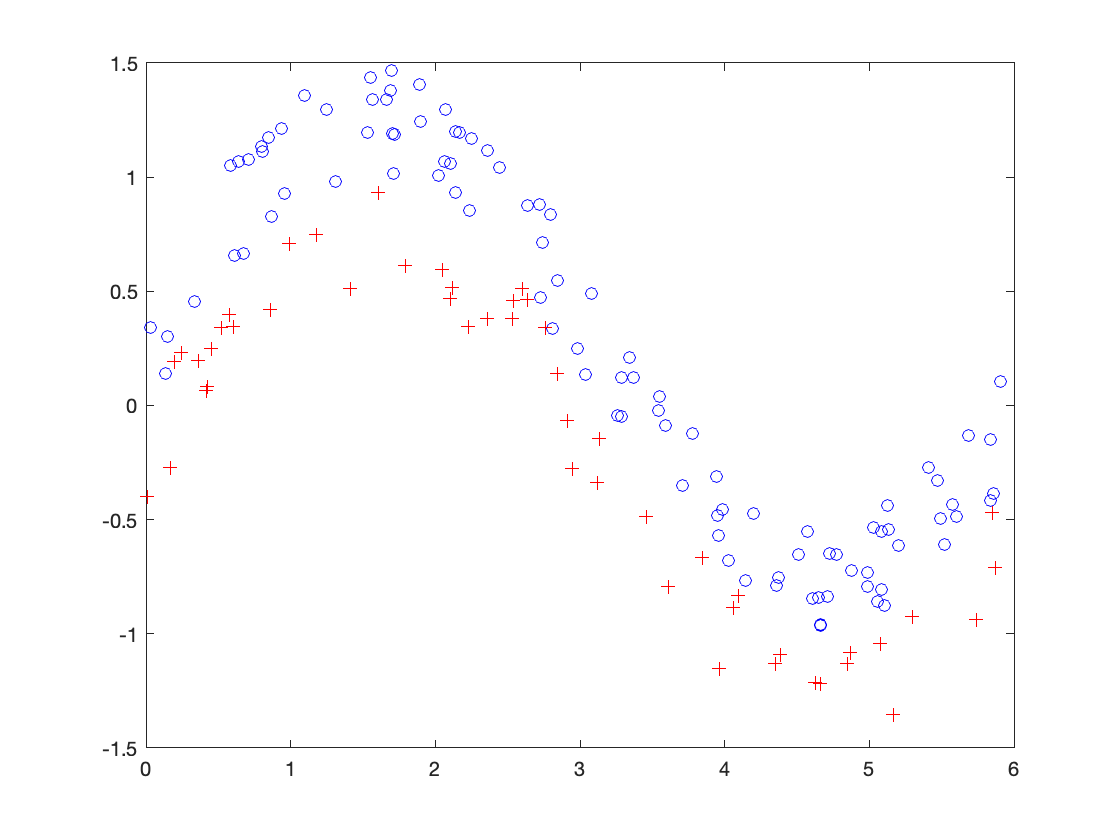

% Soft SVM with a polynomial kernel
X = [X0; X1];
y = [-ones(m0,1); +ones(m1,1)];
K_poly = (1 + X*X').^3;
lambda = 1e-2;

[a_poly,b_poly] = kernel_svm(K_poly,lambda,m0,m1);

% visualize the boundary produced by SVM with the polynomial kernel
f = @(xx,yy) a_poly'*(1+X*[xx;yy]).^3 - b_poly;
fcontour(f,[0,6,-2,2],'k-.','LevelList',0,'LineWidth',2)

#### In the second example, one utilizes an exponetial kernel. 

As usual, the blue dots are labeled negatively and the red crosses positively.

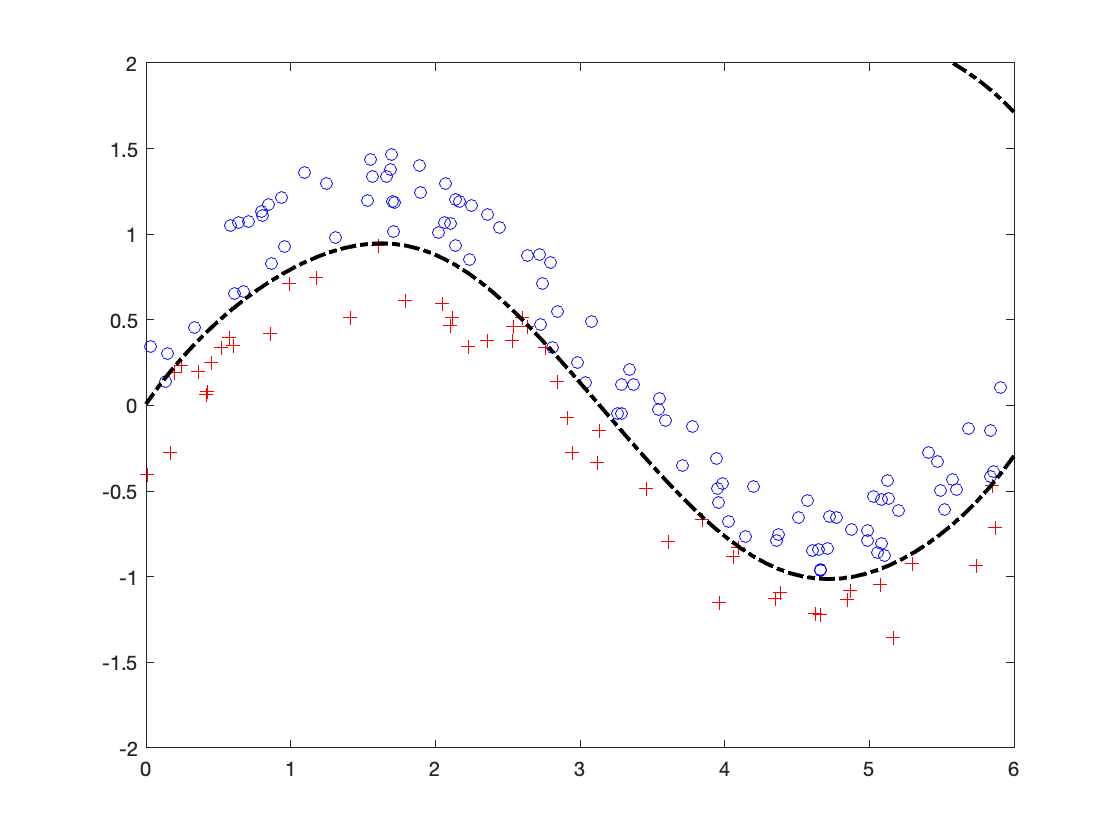

% generate the data
clear all; clc;
m0 = 50;
m1 = 100;
r0 = 1.1*sqrt(rand(m0,1));
theta0 = 2*pi*rand(m0,1);
r1 = 0.8+sqrt(rand(m1,1));

theta1 = 2*pi*rand(m1,1);
X = [r0.*cos(theta0), r0.*sin(theta0);...
     r1.*cos(theta1), r1.*sin(theta1)];
y = [-ones(m0,1); +ones(m1,1)];
figure(4)
plot(X(1:m0,1),X(1:m0,2),'bo',X(m0+1:end,1),X(m0+1:end,2),'r+')
hold on

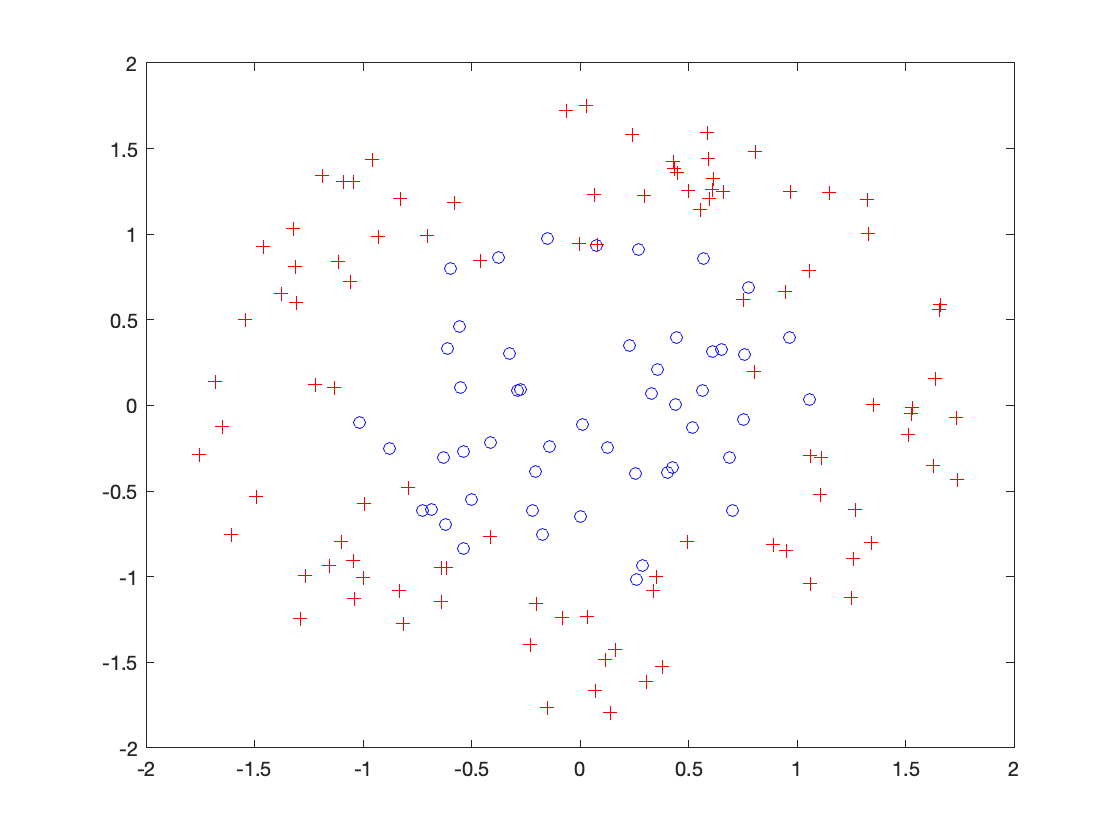

% Soft SVM with an exponential kernel
m = m0+m1;
K_expo = zeros(m,m);
sigma = 1;
for i = 1:m
    for j = 1:m
    K_expo(i,j) = exp(-norm(X(i,:)-X(j,:))/2/sigma^2);
    end
end
lambda = 1e-1;

[a_expo,b_expo] = kernel_svm(K_expo,lambda,m0,m1);

% visualize the boundary produced by SVM with the exponential kernel
f = @(xx,yy) a_expo'*exp( -sqrt(diag(X*X') - 2*X*[xx;yy] + xx^2+yy^2)/2/sigma^2 )...
    - b_expo; 
fcontour(f,[-2,2,-2,2],'k-.','LevelList',0,'LineWidth',2)

#### Here is the function performing kernel SVM for a generic kernel

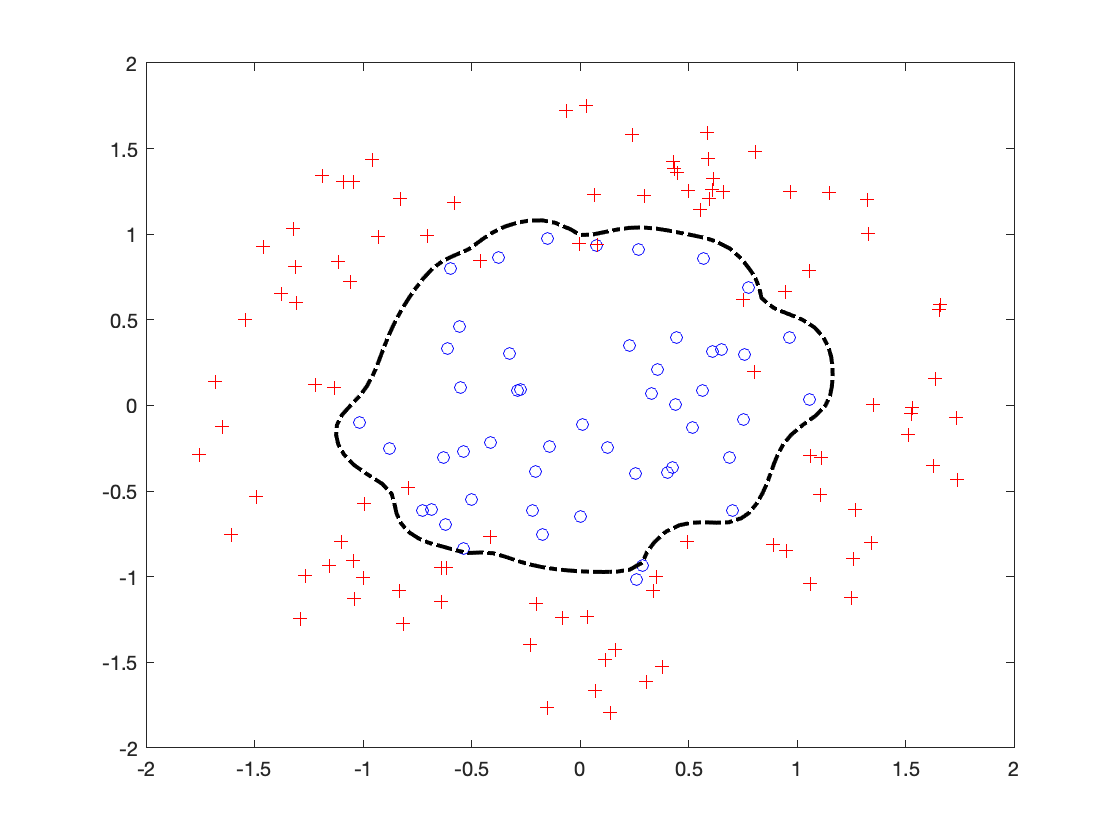

function [a,b] = kernel_svm(K,lambda,m0,m1)
cvx_quiet true
cvx_begin
variable a(m0+m1)
variable b
variable xi(m0+m1) nonnegative
minimize ( a'*K*a + (1/lambda)*sum(xi) )
subject to
K(1:m0,:)*a-b <= -1+xi(1:m0)
K(m0+1:end,:)*a-b >= 1-xi(m0+1:end)
cvx_end
end